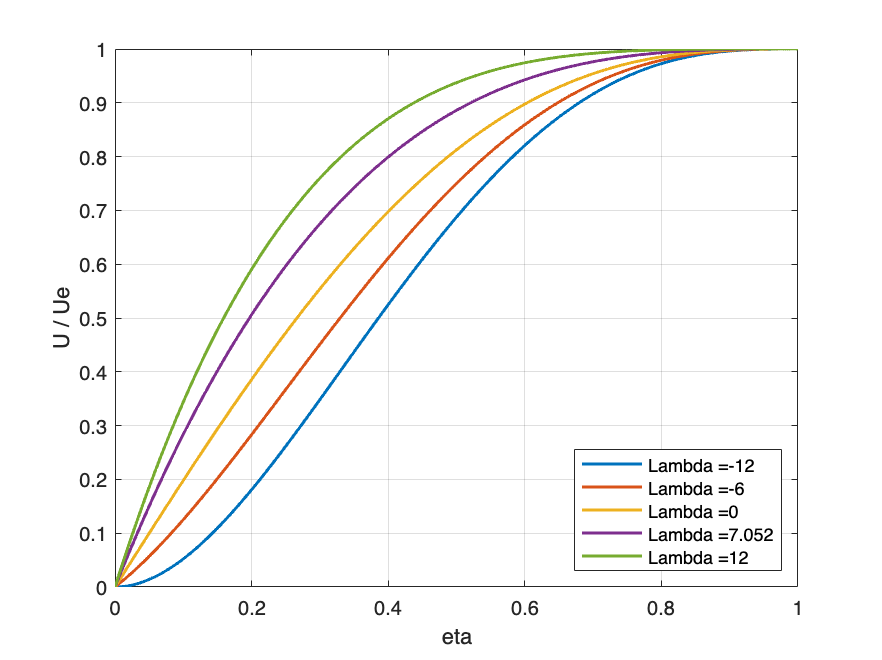


L = [-12 -6 0 7.052 12];

eta = linspace(0,1,1000);

for j = 1:length(L)

    lambda = L(j);

    for i = 1:length(eta)

        u_ue(i) = (2*eta(i) - 2*eta(i).^3 + eta(i).^4) + ...
            (lambda/6) * (eta(i) - 3*eta(i).^2 + 3*eta(i)^3 - eta(i).^4);
    end

    plot(eta,u_ue,'DisplayName',"Lambda =" + num2str(L(j)),'LineWidth',1.5)
    xlabel('eta')
    ylabel('U / Ue')
    grid on
    hold on
    legend(Location="southeast")
end

hold off